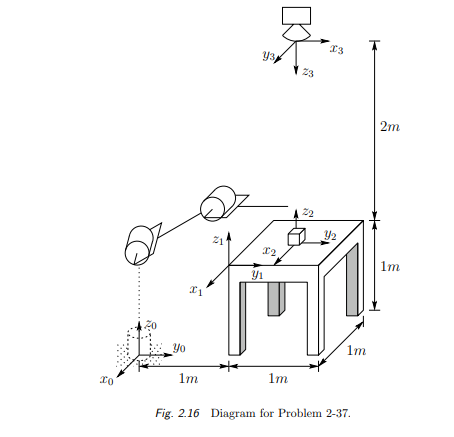

Consider the diagram of Figure 2.16. A robot is set up 1 meter from a table. The table top is 1 meter high and 1 meter square. A frame o1x1y1z1 is fixed to the edge of the table as shown. A cube measuring 20 cm on a side is placed in the center of the table with frame o2x2y2z2 established at the center of the cube as shown. A camera is situated directly above the center of the block 2m above the table top with frame o3x3y3z3 attached as shown. Find the homogeneous transformations relating each of these frames to the base frame o0x0y0z0. Find the homogeneous transformation relating the frame o2x2y2z2 to the camera frame o3x3y3z3. 

The transformations between frames 0 and 1, and 1 and 2 are easily shown through translations only. However the transformations between 2 and 3 requires rotations. 

syms theta

H_0_1 = [1 0 0 0; 0 1 0 1; 0 0 1 1; 0 0 0 1]

H_0_1 =      1     0     0     0
     0     1     0     1
     0     0     1     1
     0     0     0     1


H_1_2 = [1 0 0 -0.5; 0 1 0 0.5; 0 0 1 0; 0 0 0 1]

H_1_2 =     1.0000         0         0   -0.5000
         0    1.0000         0    0.5000
         0         0    1.0000         0
         0         0         0    1.0000


 We can match the rotation between frames 2 and 3 with a 180 degree rotation in y followed by a 90 degree rotation in z.

H_2_3_Translation = [1 0 0 0; 0 1 0 0; 0 0 1 2; 0 0 0 1]

H_2_3_Translation =      1     0     0     0
     0     1     0     0
     0     0     1     2
     0     0     0     1



H_y_rot = [cosd(theta) 0 sind(theta) 0; 0 1 0 0; -sind(theta) 0 cosd(theta) 0; 0 0 0 1]

$$H\_y\_rot = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\theta }{180}\right) & 0 & \sin\left(\frac{\pi \,\theta }{180}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\frac{\pi \,\theta }{180}\right) & 0 & \cos\left(\frac{\pi \,\theta }{180}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_z_rot = [cosd(theta) -sind(theta) 0 0; sind(theta) cosd(theta) 0 0; 0 0 1 0; 0 0 0 1]

$$H\_z\_rot = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\theta }{180}\right) & -\sin\left(\frac{\pi \,\theta }{180}\right) & 0 & 0\\ \sin\left(\frac{\pi \,\theta }{180}\right) & \cos\left(\frac{\pi \,\theta }{180}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H_2_3_y_rot = subs(H_y_rot, theta, 180)

$$H\_2\_3\_y\_rot = \left(\begin{array}{cccc} -1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & -1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_2_3_z_rot = subs(H_z_rot, theta, 90)

$$H\_2\_3\_z\_rot = \left(\begin{array}{cccc} 0 & -1 & 0 & 0\\ 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H_2_3 = H_2_3_Translation*H_2_3_y_rot*H_2_3_z_rot

$$H\_2\_3 = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 1 & 0 & 0 & 0\\ 0 & 0 & -1 & 2\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Lastly we can represent everything in reference to frame zero by multilplying out the homogenous TFs we have

H_0_2 = H_0_1*H_1_2

H_0_2 =     1.0000         0         0   -0.5000
         0    1.0000         0    1.5000
         0         0    1.0000    1.0000
         0         0         0    1.0000



H_0_3 = H_0_2*H_2_3

$$H\_0\_3 = \left(\begin{array}{cccc} 0 & 1 & 0 & -\frac{1}{2}\\ 1 & 0 & 0 & \frac{3}{2}\\ 0 & 0 & -1 & 3\\ 0 & 0 & 0 & 1 \end{array}\right)$$